# Example 1: First Demonstration Test Problem

## Introduction

This is a simple demonstration problem taken from [[1](https://www.researchgate.net/publication/323339565_A_Practical_Grid-Based_Alternative_Method_to_Advective_Particle_Tracking)] to test the double delineation approach (DDA). It simulates diagonally oriented groundwater flow between a pair of injection and pumping wells located at the lower left and upper right corners of a homogeneous, isotropic aquifer, respectively. 

We begin by clearing all variables in the workspace and then loading the relevant length and time constant units.

clear;                              % Clear all variables in the workspace
setLengthUnitsInWorkspace();        % Set length units in the base workspace
setTimeUnitsInWorkspace(2024);      % Check for leap year and set time units 

## Setup a Cartesian Grid with Discrete Aquifer Properties

The `cartGrid` function creates a three-dimensional grid with a uniform grid size along each axis. In this case, we consider an aquifer that is 100 meters long and 100 meters wide (along the X and Y axes) and 1 meter deep. The grid spacing is set to 1 meter in all directions, resulting in a total of 100 x 100 = 10,000 cells.

Grid = cartGrid(0:1:100, 0:1:100, 0:1:1);

Next, the grid is populated with discrete aquifer properties required for groundwater flow and travel time simulations. These properties include hydraulic conductivity and effective porosity. This data is appended to the '*properties*' field of the grid structure returned by the `cartGrid` function.

The hydraulic conductivity is represented as a 3 x Nx x Ny x Nz array, holding values of the hydraulic conductivity tensor along the principal directions for each cell. This structure allows for the representation of aquifer heterogeneity and directional anisotropy. In this case, we will consider a homogeneous and isotropic aquifer with a constant hydraulic conductivity of 10 meters per day (note that you can directly introduce non-SI units). 

% Cell-wise hydraulic conductivity of the aquifer
Grid.properties.hydraulic_conductivity = (1*meter/day) * ones(3, Grid.Nx, Grid.Ny, Grid.Nz);

The porosity is represented as a Nx x Ny x Nz array containing individual porosity values for each cell. In this case, we will assume a uniform porosity of 25% throughout the aquifer. 

% Cell-wise porosity of the aquifer
Grid.properties.porosity = 0.25*ones(Grid.Nx,Grid.Ny,Grid.Nz);

We also create an auxiliary grid using the `cartGrid` command. This grid has the same planar dimensions and spacing as the computational grid. Its primary purpose is to facilitate visualizations, which typically require two-dimensional grids. This is always the case for a single-layer model.

% Planar two-dimensional grid to be used for subsequent visualizations
G2D = cartGrid(0:1:100, 0:1:100);

## Add Injection and Production Wells

Here, we add the wells using the `verticalWell` function. This function expects an array of structures containing the properties of each well as its first parameter. The next parameter is the previously constructed grid, followed by the planar I and J grid indices (i.e., column and row) of the well. Then, the total injection or production flow rate is specified, along with an array of K grid indices indicating where the well is perforated. Finally, a series of optional parameter/value pairs can be provided. For instance, the 'type' property must be followed by either 'injection' or 'pumping' to designate an injection or pumping well, respectively.

% Pumping/injection flow rate in cubic meters per hour
Q = 20*meter^3/hour;        

% Add injection well 
W = verticalWell([], Grid, 1, 1, 1, Q, 'type', 'injection', 'name', 'I');

% Add pumping well 
W = verticalWell(W, Grid, 100, 100, 1, Q, 'type', 'pumping', 'name', 'P');

Next, for verification purposes, we plot the computational grid and decorate it with blue and red points to represent the injection and production wells, respectively.

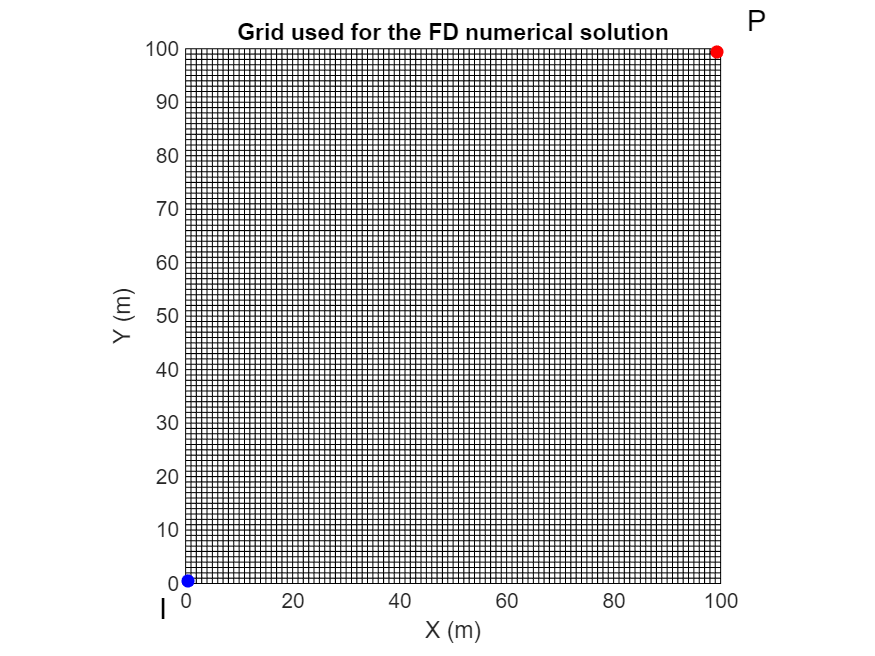

figure;                                             % creates a new figure window for plotting
plotGrid(G2D, 'faceAlpha', 0);                      % plot the two-dimensional grid 
axis tight equal;                                   % fit data to axes limits + maintain aspect ratio  
xlabel('X (m)'); ylabel('Y (m)');                   % plot X, Y axes labels
title('Grid used for the FD numerical solution');   % plot title
hold on;                                            % overlay subsequent plots until "hold off;"
scatter(0.5,0.5,40,"blue","filled");                % plot single blue point @ lower left corner
scatter(99.5,99.5,40,"red","filled");               % plot single red point @ upper right corner
text([-5,105], [-5,105], {'I','P'}, 'FontSize', 14);% plot text
hold off;                                           % return to default behavior

## Simulate Steady-State Groundwater Flow

Now that all the simulation prerequisites are defined, we can proceed to simulate the steady-state groundwater heads in the aquifer. This is done by calling the `head` function, where we pass the computational grid and the wells structure as the only parameters. The function is wrapped in MATLAB's `tic` and `toc` commands to measure the elapsed simulation time.

tic; [H,V] = head(Grid, W); toc;

Number of PCG iterations = 34
Residual norm error      = 3.97931E-07
Elapsed time is 0.178250 seconds.


As shown in the output, the simulation converged in just 34 preconditioned conjugate gradient iterations, taking only a fraction of a second. By default, the numerical solver for the groundwater flow equation employs an algebraic multigrid preconditioning technique, which performs efficiently even for large-scale problems. In this small two-dimensional example, an alternative preconditioner or even a direct solver would also be suitable.

The `head` function returns the simulated groundwater head array as its first output. Additionally, a structure containing the simulated specific discharge field across the X-, Y-, and Z-oriented faces of the grid is computed using Darcy's law.

## Visualize the Results using Flownets

Now, let's examine the distribution of the simulated groundwater heads in the aquifer. First, we use the `plotContourData` function to plot the contiguous array H(:) (i.e., reshaped into a single-dimension array) of groundwater head values. Additional options include plotting filled contour lines, specifying the contour levels, their color, and width. A colormap is applied, and a colorbar is displayed. The next set of commands overlays traced streamlines using the `plotStreamline` function, which requires the specific discharge field vectors, the initial positions of the particles, and a flag indicating the direction of particle tracking. In this example, we choose initial particle positions uniformly spaced along the reverse diagonal of the domain. Streamlines are then traced in both forward and backward directions to fully visualize the flow lines connecting the two wells. 

Notice that the equipotential lines are orthogonal to the streamlines everywhere, which aligns with the flownets theory in a homogeneous and isotropic porous medium.

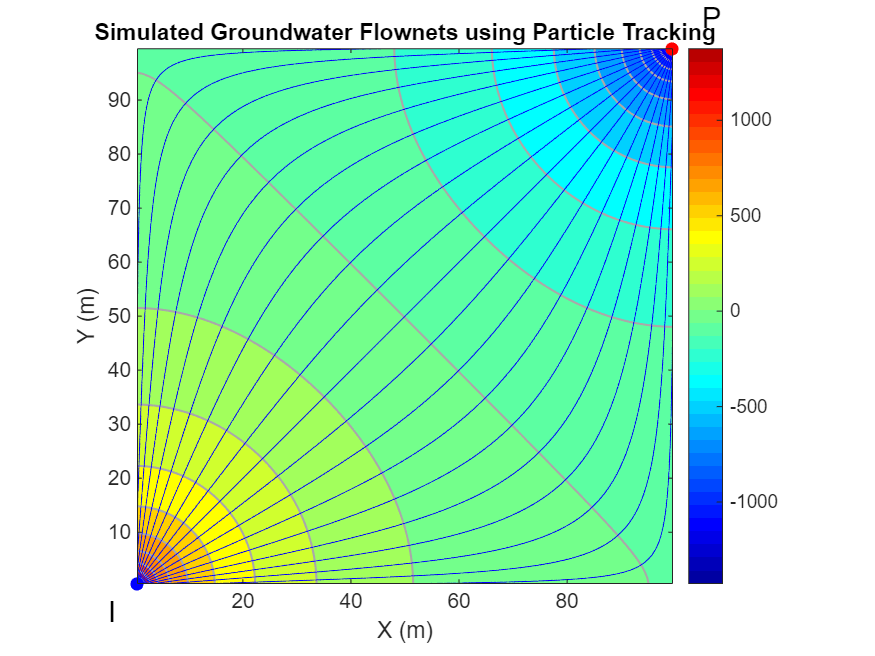

figure;                                     % creates a new figure window for plotting
opts.fill = 'on';                           % specify type of contour plot => fill between contour lines
plotContourData(G2D, H(:), opts, ...        % function that plots the head contours
    'LevelList',-1500:125:1500, ...             % add contours between -1500 m and +1500 m with 125 m interval
    'Color',rgb(Color,'darkgray'), ...          % contours color is dark gray
    'LineWidth', 1);                            % width of the contour lines
colormap(jet(41));                          % use jet colormap: blue to red
colorbar;                                   % add the colorbar
hold on;                                    % overlay subsequent plots until "hold off;"
%--- block to plot streamlines
coords = zeros(2,19);                       % initialize particles coordinates 
coords(1,:) = 5:5:95;                       % x-coordinates of the particles
coords(2,:) = 100*ones(1,19)-coords(1,:);   % y-coordinates of the particles
% plot streamlines in the groundwater flow direction with blue color
plotStreamline(V, [Grid.hx Grid.hy], coords, true, 'Color', 'b', 'LineWidth', 0.5);
% plot streamlines in the opposite groundwater flow direction with blue color
plotStreamline(V, [Grid.hx Grid.hy], coords, false, 'Color', 'b', 'LineWidth', 0.5);
%--- additional plot decorations as in the previous plot
scatter(0.5,0.5,40,"blue","filled");
scatter(99.5,99.5,40,"red","filled");
text([-5,105], [-5,105], {'I','P'}, 'FontSize', 14);
axis tight equal;                           % it data to axes limits + maintain aspect ratio
xlabel('X (m)'); ylabel('Y (m)');           % plot X, Y axes labels
title('Simulated Groundwater Flownets using Particle Tracking');   % plot title 
hold off;                                   % return to default behavior

## Simulate Forward Travel Times using the Finite-Difference Method

In groundwater modeling practice, it is common to use particle tracking for advective transport simulations [2]. An alternative approach introduced in [[1](https://www.researchgate.net/publication/323339565_A_Practical_Grid-Based_Alternative_Method_to_Advective_Particle_Tracking)] involves solving the following advection equation:

$\mp \mathit{\mathbf{v}}\ldotp \nabla \tau =\phi$ subject to $\tau =0\;\textrm{in}\;\Gamma_{\textrm{in}} \;\textrm{or}\;\Gamma_{\textrm{out}}$

where $\mathit{\mathbf{v}}$ is the specific discharge field, $\tau$ is the forward or backward travel time (which is determined by the positive or negative sign in front of the equation, respectively), and $\phi$is the effective porosity. $\Gamma_{\textrm{in}}$ and $\Gamma_{\textrm{out}}$ represent the inflow and outflow boundaries, respectively. 

The `travelTime` function solves this advection equation using a first-order upwind scheme. It requires the grid, the specific discharge structure, the wells structure, and the flow direction (which corresponds to the direction used in particle tracking methods) as inputs.

tic;
ftt = travelTime(Grid, V, W, true);
toc;

Elapsed time is 0.024451 seconds.


The numerical solution is obtained almost instantaneously. Our numerical experiments in [[3](https://www.researchgate.net/publication/341540687_On_Solving_Groundwater_Flow_and_Transport_Models_with_Algebraic_Multigrid_Preconditioning)] demonstrate that the  sparse direct solver, used by default, is the most efficient option, even for large-scale problems. The `travelTime` function returns an array of forward (or backward) travel times calculated for each cell in the grid.

## Visualize Isochrones using DDA

Visualizing the isochrones using the DDA is straightforward; it involves simply contouring the forward travel time values computed for the grid cells. This can be accomplished using the `plotContourData` function, as previously explained when we contoured the groundwater head values. Since we used SI units for internal calculations in this example, the travel time values are in seconds. Therefore, we divide the travel time array by the number of seconds in a day and plot all isochrones between 0.5 and 5 days at 0.5-day intervals. The resulting figure reproduces the same results shown in [[1](https://www.researchgate.net/publication/323339565_A_Practical_Grid-Based_Alternative_Method_to_Advective_Particle_Tracking)] for this problem.

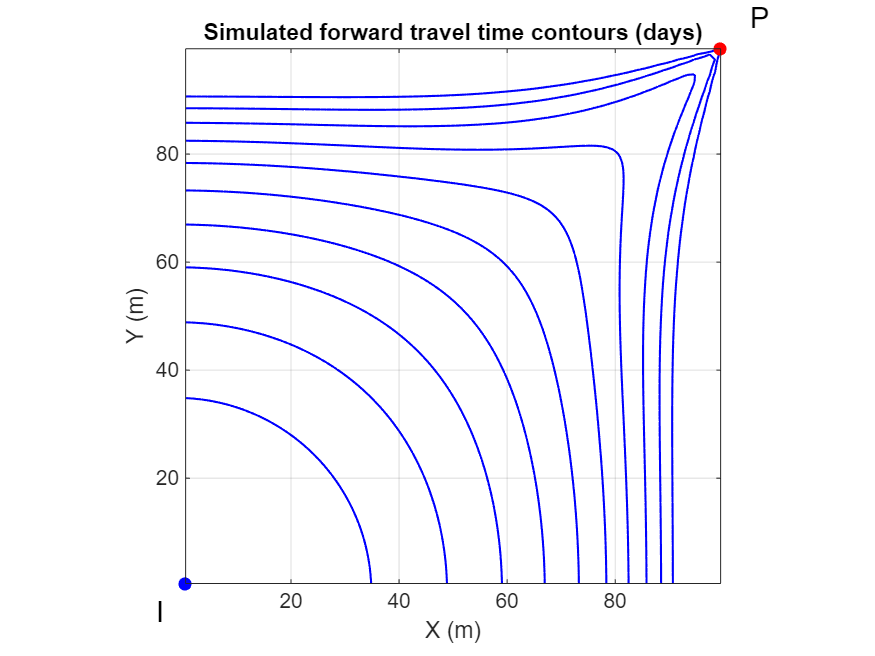

figure; 
opt.fill = 'off';
plotContourData(G2D,ftt/day,opt,...
    'LevelList',0:0.5:5,...
    'LineStyle','-',...
    'LineWidth',1,...
    'LineColor','blue');
axis([0 100 0 100]); 
xticks(0:20:100);
yticks(0:20:100);
axis equal tight;
grid on; 
title('Simulated forward travel time contours (days)'); 
xlabel('X (m)'); ylabel('Y (m)');
hold on; 
scatter(0.5,0.5,40,"blue","filled");
scatter(99.5,99.5,40,"red","filled");
text([-5,105], [-5,105], {'I','P'}, 'FontSize', 14);
hold off;

It is possible to post-process the results of a particle tracking simulation, as done in [[1](https://www.researchgate.net/publication/323339565_A_Practical_Grid-Based_Alternative_Method_to_Advective_Particle_Tracking)], for comparison purposes to construct the isochrones through interpolation. However, as discussed in the same paper, this technique is not very accurate because it depends on the density of the streamlines and the number of points (i.e., the order of numerical integration) along each streamline. Additionally, this interpolation becomes quite complex in three-dimensional aquifer systems.

## Visualize flownets using DDA

In this section, we demonstrate that, similar to particle tracking, the DDA can be used to visualize groundwater flownets. To achieve this, we first calculate the backward travel time distribution using a finite-difference approximation on the model grid. We then combine the forward and backward travel time distributions to obtain the cell-wise residence time distribution within the aquifer. This represents the time required for inflow lines from the injection well to reach the pumping well. The resulting time distribution aligns with the definition of flow lines, as the iso-contours of the residence time field correspond to flow lines at specific residence times.

To create a groundwater flownets plot, we first plot the equipotential lines as before. Next, we overlay specific iso-values of the residence time (in days). Note that a log10 distribution is used to ensure the streamlines remain evenly spaced across different areas.  

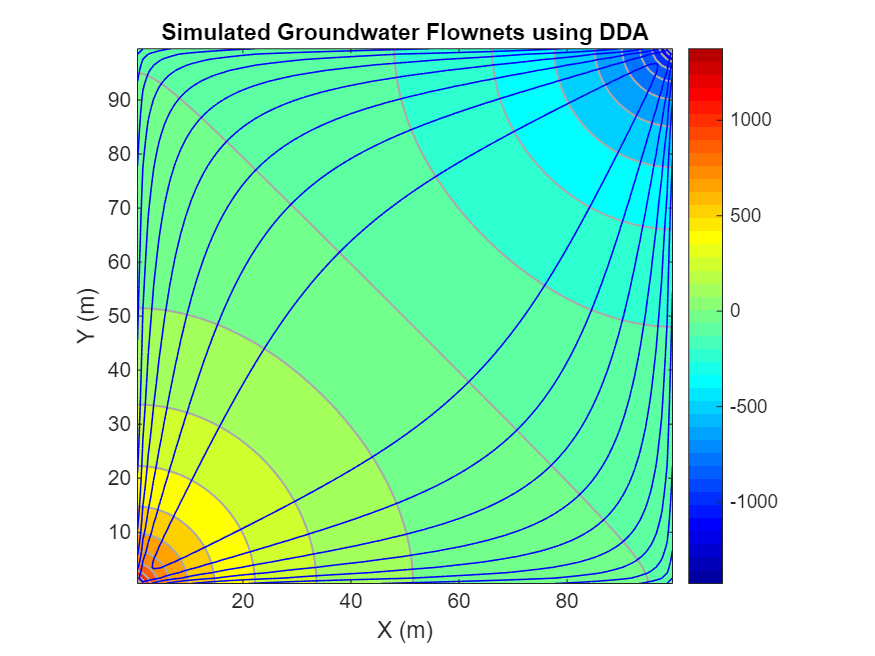

% Simulate backward travel time 
btt = travelTime(Grid, V, W, false);

% Draw equipotential lines
opts.fill = 'on';                           
plotContourData(G2D, H(:), opts, ...        
    'LevelList',-1500:125:1500, ...             
    'Color',rgb(Color,'darkgray'), ...          
    'LineWidth', 1);                            
colormap(jet(41));                          
colorbar;                                   
hold on;                                   
% Draw iso-contours of the residence time 
opt.fill = 'off';
plotContourData(G2D,(ftt+btt)/day,opt,...
    'LevelList',logspace(log10(1),log10(25),19),...
    'LineStyle','-',...
    'LineWidth',0.75,...
    'LineColor','blue');
axis tight equal;                           
xlabel('X (m)'); ylabel('Y (m)');           
title('Simulated Groundwater Flownets using DDA'); 
hold off;

Similar to particle tracking, the DDA can also generate groundwater flownets, but there are key differences between the two methods. With particle tracking, the modeler controls the starting positions of the particles, releasing them either forward or backward to trace streamlines. However, there is no control over the time it takes (i.e., the residence time) for the streamlines to reach a sink or source as this is a result of the particle tracking process. In contrast, the DDA allows for finer control over streamlines associated with specific residence time values, but it cannot track streamlines that originate or terminate at a specific location. 

## **Discussion**

In particle tracking, the ability to control starting points is a significant advantage, allowing modelers to focus on specific areas of interest, particularly at a local scale. This is useful when tracking the movement of groundwater from well-defined locations, such as known contamination sources or injection wells, where spatial precision is critical. However, a major limitation is the lack of control over the residence time. While particle tracking can theoretically capture the time groundwater takes to move between sources and sinks, doing so comprehensively across the entire model domain often proves laborious. It requires releasing particles at many different points and directions, and integrating these results to form a complete picture of the system’s global behavior is both time-consuming and difficult to achieve in practice. Consequently, particle tracking tends to be more effective for spatially targeted analysis rather than for capturing a full overview of system-wide flow times.

In contrast, the DDA's strength lies in its ability to directly generate streamlines based on residence time distributions, offering an immediate view of flow behavior over time. This can be particularly valuable in contexts where understanding how long it takes groundwater to travel through an aquifer is more important than knowing the precise locations of the streamlines. For example, DDA is highly effective for studying temporal dynamics in regional aquifer systems, assessing the sustainability of groundwater resources, or evaluating the efficiency of remediation efforts over time. The method’s ability to provide a global picture of residence times makes it especially suitable for system-wide assessments. However, its drawback is the lack of control over where streamlines start and end. This can make DDA less practical for studies that require precise tracking of groundwater flow from or to specific points, such as monitoring wells or point sources of contamination, where a finer spatial resolution is essential.

In essence, these methods offer complementary strengths: particle tracking excels in spatial control and is ideal for localized, detailed studies where understanding the pathways of groundwater from specific points is crucial. The DDA, on the other hand, is better suited for temporal analysis and provides a more holistic view of groundwater flow behavior over time, making it ideal for system-wide assessments where residence time is the key focus.

Moreover, the DDA method, as presented in [[1](https://www.researchgate.net/publication/323339565_A_Practical_Grid-Based_Alternative_Method_to_Advective_Particle_Tracking)], offers additional advantages that will be demonstrated in the following examples. Notably, it can calculate both steady-state and time-dependent capture zones for injection and production wells. The method also has the potential to quantify the contributions of various sources to the flow rates of pumping wells, and vice-versa. Additionally, it can be applied to perform advanced analyses of interactions between pumping and injection wells. To explore these capabilities in more detail, we invite you to continue with the upcoming tutorials in the DDA toolbox.

## References 

[1] [Sbai, M.A. (2018). A Practical Grid-Based Alternative Method to Advective Particle Tracking. Groundwater, 56(6), 881-892. https://doi.org/10.1111/gwat.12646](https://www.researchgate.net/publication/323339565_A_Practical_Grid-Based_Alternative_Method_to_Advective_Particle_Tracking)

[2] Anderson, M.P., W.W. Woessner, and R.J. Hunt. (2015). *Applied Groundwater Modeling—Simulation of Flow and Advective Transport*, 2nd ed. London, UK: Elsevier.

[3] [Sbai, M.A., & Larabi, A. (2020). On Solving Groundwater Flow and Transport Models with Algebraic Multigrid Preconditioning. Groundwater, 59(1), 100-108. https://doi.org/10.1111/gwat.13016](https://www.researchgate.net/publication/341540687_On_Solving_Groundwater_Flow_and_Transport_Models_with_Algebraic_Multigrid_Preconditioning)

Author: M.A. Sbai, Ph.D.

Copyright (C) 2024 Mohammed Adil Sbai

This program is free software: you can redistribute it and/or modify it under the terms of the GNU General Public License as published by the Free Software Foundation, either version 3 of the License, or (at your option) any later version.

This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE. See the GNU General Public License for more details.

You should have received a copy of the GNU General Public License along with this program. If not, see <http://www.gnu.org/licenses/>.